# Question 1b

clear all; close all; clc

g = 0 %Assume zero gravity

g = 0

l1 = 0.5;
l2 = 0.5;
rho = 1000; %Assume this is the density of the material
r_outer = 0.1;
r_inner = 0.005;
m1 = rho*l1*pi*(r_outer^2 - r_inner^2);
m2 = rho*l2*pi*(r_outer^2 - r_inner^2);


L(1) = Link('revolute','d', 0, 'a', 0, 'alpha', 0 ,'modified');
L(2) = Link('revolute','d', 0, 'a', l1, 'alpha', 0 ,'modified');
L(3) = Link('revolute','d', 0, 'a', l2, 'alpha', 0 ,'modified');

RR1 = SerialLink(L, 'name', '2D-1-RR');


PC1 = [l1/2; 0 ; 0];
PC2 = [l2/2; 0 ; 0];

Ix = 0.5*m1*(r_outer^2 + r_inner^2);
Iy = Ix/2 + (1/12)*m1*l1^2; Iz = Ix/2 + + (1/12)*m2*l2^2;

IC1 = [Ix 0 0; 0 Iy 0; 0 0 Iz]

IC1 =     0.0785         0         0
         0    0.3657         0
         0         0    0.3657


IC2 = [Ix 0 0; 0 Iy 0; 0 0 Iz]

IC2 =     0.0785         0         0
         0    0.3657         0
         0         0    0.3657


f3 = [-10;0;0]; 
n3 = [0;0;10]; 

w0 = zeros(3,1);
wd0 = zeros(3,1); 

v0 = zeros(3,1); 
vd0 = [0 ; 0 ; 0];

t1_initial = -acos(0.45/0.5)

t1_initial = -0.4510

t2_initial = 2*acos(0.45/0.5)

t2_initial = 0.9021

t1_final = -acos(0.05/0.5)

t1_final = -1.4706

t2_final = 2*acos(0.05/0.5)

t2_final = 2.9413


N = 100;
t1 = linspace(t1_initial, t1_final, N+2)

t1 =    -0.4510   -0.4611   -0.4712   -0.4813   -0.4914   -0.5015   -0.5116   -0.5217   -0.5318   -0.5419   -0.5520   -0.5621   -0.5722   -0.5823   -0.5924   -0.6025   -0.6125   -0.6226   -0.6327   -0.6428   -0.6529   -0.6630   -0.6731   -0.6832   -0.6933   -0.7034   -0.7135   -0.7236   -0.7337   -0.7438   -0.7539   -0.7640   -0.7741   -0.7842   -0.7943   -0.8044   -0.8144   -0.8245   -0.8346   -0.8447   -0.8548   -0.8649   -0.8750   -0.8851   -0.8952   -0.9053   -0.9154   -0.9255   -0.9356   -0.9457


t2 = linspace(t2_initial, t2_final, N+2)

t2 =     0.9021    0.9222    0.9424    0.9626    0.9828    1.0030    1.0232    1.0434    1.0636    1.0838    1.1040    1.1241    1.1443    1.1645    1.1847    1.2049    1.2251    1.2453    1.2655    1.2857    1.3059    1.3260    1.3462    1.3664    1.3866    1.4068    1.4270    1.4472    1.4674    1.4876    1.5078    1.5279    1.5481    1.5683    1.5885    1.6087    1.6289    1.6491    1.6693    1.6895    1.7097    1.7298    1.7500    1.7702    1.7904    1.8106    1.8308    1.8510    1.8712    1.8914


totalTime = 4;
dt = 4/N;
dt1 = (diff(t1))/dt

dt1 =    -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524


dt2 = (diff(t2))/dt

dt2 =     0.5048    0.5048    0.5048    0.5048    0.5048    0.5048    0.5048    0.5048    0.5048    0.5048    0.5048    0.5048    0.5048    0.5048    0.5048    0.5048    0.5048    0.5048    0.5048    0.5048    0.5048    0.5048    0.5048    0.5048    0.5048    0.5048    0.5048    0.5048    0.5048    0.5048    0.5048    0.5048    0.5048    0.5048    0.5048    0.5048    0.5048    0.5048    0.5048    0.5048    0.5048    0.5048    0.5048    0.5048    0.5048    0.5048    0.5048    0.5048    0.5048    0.5048


ddt1 = (diff(t1,2))/dt^2

ddt1 = 	1.0e+-12 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0694   -0.1388    0.1388   -0.1388    0.1388   -0.1388    0.1388   -0.1388    0.0694         0    0.0694   -0.1388    0.1388   -0.1388    0.1388   -0.1388    0.1388   -0.1388    0.1388   -0.1388    0.1388   -0.1388    0.0694


ddt2 = (diff(t2,2))/dt^2

ddt2 = 	1.0e+-12 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   -0.1388    0.2776   -0.2776    0.2776   -0.2776    0.2776   -0.2776    0.2776   -0.1388         0   -0.1388    0.2776   -0.2776    0.2776   -0.2776    0.2776   -0.2776    0.2776   -0.2776    0.2776   -0.2776    0.2776   -0.1388



for j=1:N

    th = [t1(j) t2(j) 0];

    T_01 = RR1.A([1], th);
    T_12 = RR1.A([2], th);
    T_2T = RR1.A([3], th);
    T_0T = RR1.A([1 2 3], th);

    [R_01, P_01] = tr2rt(T_01); R_10 = transpose(R_01);
    [R_12, P_12] = tr2rt(T_12); R_21 = transpose(R_12);
    [R_2T, P_2T] = tr2rt(T_2T); R_32 = transpose(R_2T);
    [R_0T, P_0T] = tr2rt(T_0T);

    x(j) = P_0T(1); y(j) = P_0T(2);


    % i = 0
    w1 = R_10 * w0 + dt1(j)*R_01(1:3,3);
    wd1 = R_10 * wd0 + R_10 * cross(w0, dt1(j)*R_01(1:3,3)) + ddt1(j)*R_01(1:3,3);
    
    vd1 = R_10 * (cross(wd0, P_01) + cross(w0, cross(w0, P_01)) + vd0);
    vcd1 = cross(wd1,PC1) + cross(w1,cross(w1,PC1)) + vd1;
    
    F1 = m1 * vcd1 ;
    N1 = IC1 * wd1 + cross(w1,IC1*w1);
    
    % i = 1
    w2 = R_21 * w1 + dt2(j)*R_12(1:3,3);
    wd2 = R_21 * wd1 + R_21 * cross(w1, dt2(j)*R_12(1:3,3)) + ddt2(j)*R_12(1:3,3);
    
    vd2 = R_21 * (cross(wd1, P_12) + cross(w1, cross(w1, P_12)) + vd1);
    vcd2 = cross(wd2,PC2) + cross(w2,cross(w2,PC2)) + vd2;
    
    F2 = m2 * vcd2 ;
    N2 = IC2 * wd2 + cross(w2,IC2*w2);
    
    % i = 2
    f2 = R_2T * f3 + F2;
    n2(:,j) = N2 + R_2T*n3 + cross(PC2, F2) + cross(P_2T, R_2T*f3);
    
    % i = 1
    f1 = R_12 * f2 + F1;
    n1(:,j) = N1 + R_12*n2(:,j) + cross(PC1, F1) + cross(P_12, R_12*f2);
end

time = linspace(0, totalTime, N);

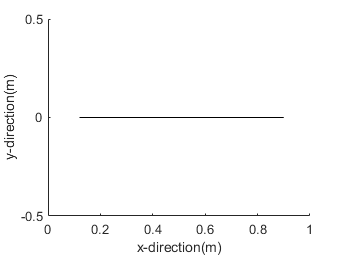

figure(1)
xlabel('x-direction(m)')
ylabel('y-direction(m)')
h = animatedline;
axis([0 1 -0.5 0.5])
for j=1:N
    addpoints(h,x(j),y(j));
    drawnow
    pause(0.1)
end

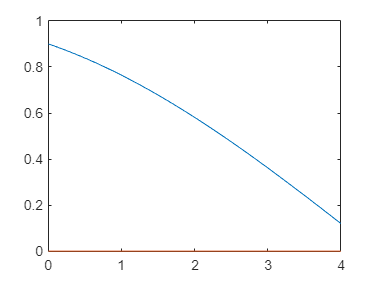

figure(2)
ylabel('x or y direction(m)')
xlabel('time(s)')
plot(time, x);
hold on
plot(time, y);
hold off

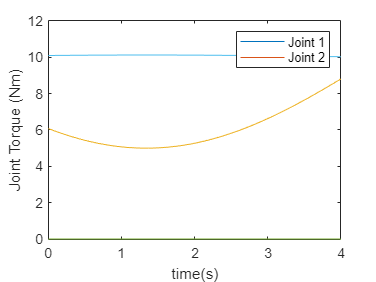

figure(3)
ylabel('Joint Torque (Nm)')
xlabel('time(s)')

plot(time, n1);
hold on
plot(time, n2);
legend('Joint 1','Joint 2')
hold off